# A Discrete Cell Division Model - Part III

**Purpose: **this assignment has two roles: (1) it equips you with an additional discrete model that you can use for your final project. It also helps you understand how and when to use the cell population model here and the one discussed in class. (2) Its second role is to make you more comfortable with discussing and understanding graphs that represent data. 

**During this assignment, you will pracitice the following: **

**Mathematical skills:** difference equations, discrete modeling

**Coding skills**: for loops, plots, vectors, assigning values, indexing

**Task: **Modify the code below to answer the questions is the 'Questions' section:

**Note**: this lesson shows you the calculations and derivations behind the model that we will use in class. They are here for transparancy purposes, and you will **not** be assessed on these derivations. 

## Intro 

In class, we worked with a cell division model that used *discrete steps* and the concept of *daughter* cells. At each step, the cells simultaneously divided into $b$ daughter cells. We used a *difference equation* to predict the cell population number at a specified generation. But what if cells die, too? Here, we add in 'death' to our previous model that only considered 'birth'.  

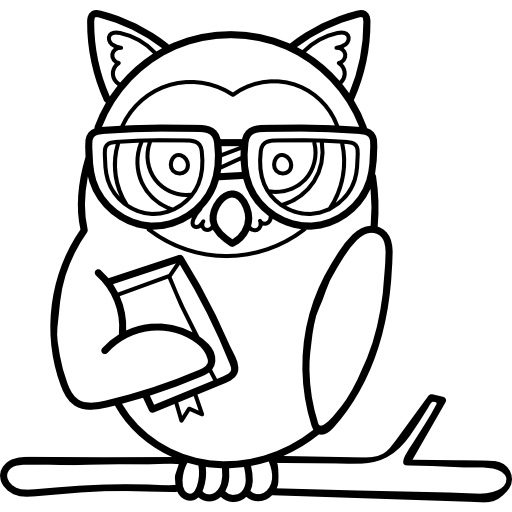  You can edit the blank fields!

First, we start with our simpler familiar model:

$M_{k+1} =M_k \times b$                                                      Equation 1

Set M0, n, and b such that we start with** 3** cells, each cell divides into **2**, and the equation predicts the population at the **6**th generation.

## Code

M0 = 5;

n = 4;

b = 2;

### Difference Equations

As we saw in class, the following equation predicts the population number after the nth division if we only consider birth and ignore death: 

$M_n =M_0 {\;b}^n$                                                      Equation 2

The function below, uses Equation 2 to calculate $M_n$:

Mn = MnCalculator(M0, b,n) 

### Graphs 1

Visualization of data usually helps us better understand it. Here, we graph the population number at each generation as a function of the generation before including death in our model:

figure(1)
d = 0;
plotGenerations(M0,b,d,n)

## Including Death

Now, let's say after each division, 2 out of 10 cells die. 

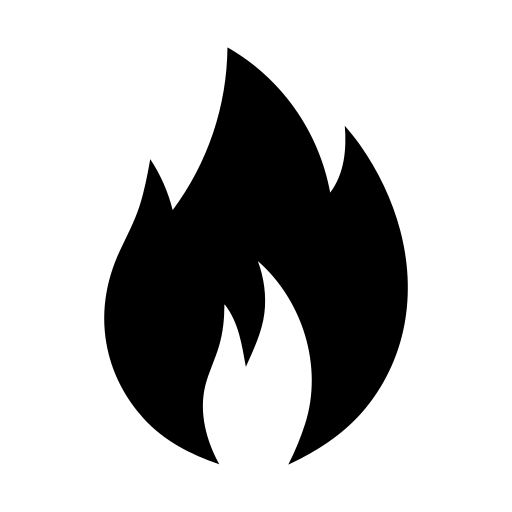 **Hot** **Question:** How do we turn the fraction into a percentage?

 answers(2)

In other words, if 2 out of 10 cells die, or 2/10 cells die, we have:

(number of cells dying after each division) = $\frac{2}{10}\times \;$(the number of cells after each division before death)

**Hot** **Question:** Do we subtract this number from the total population number or add it to get the number of cells after death?

 answers(1)

We will use `d` to represent this variable. That is

(number of cells dying after each division) = $d\times \;$(the number of cells after each division before death)

and here

d = 0.6;

### Difference Equations

Now, we modify Equation 1 and Equation 2 to consider the effect of death:

After subtracting the number of dead cells from Equation 1, we have

$M_{k+1} =M_k \times b-M_{k\;} \times b\times d=M_{k\;} b\left(1-d\right)$.                                 Equation 3

This implies 

 $M_n =M_0 {b^n \left(1-d\right)}^n$.                                                                   Equation 4

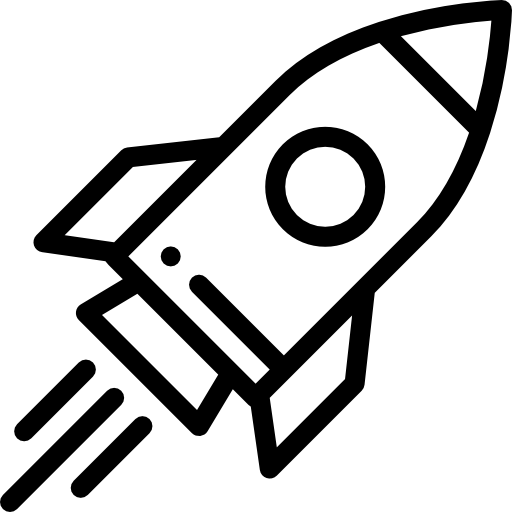 **pace check: **notify the instructor if this is going too fast!

Let's use Equation 4 to compare the number of cells to the case where we did not have death:

MnWithdeath(M0,b,d,n)

### Graphs 2

Visualization of data usually helps us better understand it. Here, we graph the population number at each generation as a function of the generation with one graph ignoring death and one including death:

figure(1)
plotGenerations(M0,b,d,n)

## Questions 1

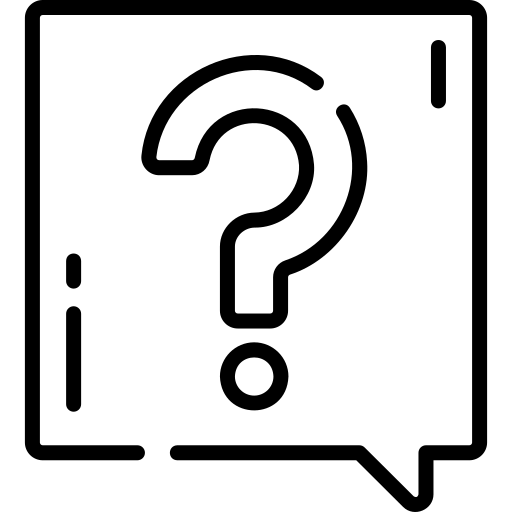 **Question 1:** What is the final population if you change d to 1/10? What is it if you set d = 6/10?

 **Question 2:** Can d have a value greater than 1? Why or why not?

 **Question 3:** Does anything about the population number after considering the fraction of dead cells make you uneasy?

### Questions Related to the Graphs

 **Question 4:** Does the form of the graph above change after including death in the model?

 **Question 5:** Is the population increasing or decreasing after including death?

## Graphs 3

Almost all the graphs that we have seen so far have **exponential** form. The little edges, kinks, and corners happen because they are not *continuous*. Here, we compare them with a linear graph. Let's consider a case where the cells are not dividing but we are restocking their chamber so that at each time step, we add 1 million more cells. 

r = 1000000;

We want to know how many cells we have after 7 time steps.

n = 7;

We create an array to store the value for number of cells after each time step, and we start with M0 cells in the beginning: 

M = zeros(n+1,1);
M0 = 1000000;
M(1) = M0; % set the first element of the M vector equal to the initial cell number

Again, we can use a *for loop* to calculate the number of cells after each time step:

for k = 1:n
    M(k+1) = M(k) + r; % at each step, we add r cells
end

  Let's look at the graph:

figure
plot(0:n,M,'LineWidth',3, 'LineStyle','--')
    % insert label for the x-axis
xlabel('Time Step')
    % insert label for the y-axis
ylabel('Number of Cells')

Can you see where the linear graph gets its name from?

Now, let's compare the exponential curve and the linear one. Since the cell division model gives us exponential growth, to get an exponential curve, we can use the cell division model. First, we create a new vector to store the cell number after each division. 

MExp = zeros(n+1,1); 

Set the first element equal to the initial cell number:

MExp(1) = M0;

Again, we use a *for loop *to multiply the cell number by `b` the number of daughter cells each cell divides into at each step:

for k = 1:n
    MExp(k+1) = MExp(k) * b;
end

We can graph the results on the same plot to compare them:

figure
plot(0:n,M,'LineWidth',3, 'LineStyle','--', 'DisplayName','linear curve')
    % insert label for the x-axis
xlabel('Time Step')
    % insert label for the y-axis
ylabel('Number of Cells')
hold on
plot(0:n,MExp,'LineWidth',3, 'DisplayName','exponential curve')

## Questions 2

These questions refer to the last graph above.

 **Question 1:** What are some visual difference between a linear and an exponential graph?

 **Question 2:** Describe what you see. Is the graph showing an increase, decrease, or neither? Is the *slope* changing?

 **Question 3:** Does the starting value affect the form of the graph?

## Modeling Functions

This section contains our modeling toolbox. You can copy and paste the functions into a program and use them like calculators!

- The first function here, uses Equation 2 to calculate $M_n$.

- The second function uses Equation 4 to calculate $M_n$ with both birth and death.

- The third function uses a for loop to create a graph that shows the population number after each division up to the nth.

Function 1:

function Mn = MnCalculator(M0,b,n)

Mn = M0*b^n;

end

Function 2:

function Mn = MnWithdeath(M0,b,d,n)

Mn = M0*b^n*(1-d)^n;

end

Function 3:


function plotGenerations(M0,b,d,n)

if d > 0
    tilenumber = 2;
else 
    tilenumber = 1;
end

Generations = linspace(0,n,n+1);
M = ones(1,n);

% By multiplying the population number at each generation with b,...
% we can calculate the population number right after the division:
M(1) = M0*(b);

% we use a for loop to get the population number at each generation up to the nth    
for k = 1:1:n-1
    M(k+1) = (b)*M(k); % at each step, we multiply the number of cells by b! 
end
tiledlayout(1,tilenumber)
% panel 1
nexttile
% here, we plot the population number at each generation...
% up to the nth
plot(Generations,[M0 M], 'LineWidth', 3, 'Color','k')
% insert label for the x-axis
xlabel('Generation')
% insert label for the y-axis
ylabel('Number of Cells')
% insert title
title('population vs generation number without death')

if d > 0
    % panel 2
    nexttile
    M(1) = M0*b*(1-d);
    
    % we use a for loop to get the population number at each generation up to the nth    
    for k = 1:1:n-1
        M(k+1) = b*(1-d)*M(k); % at each step, we multiply the number of cells by b! 
    end
    % here, we plot the population number at each generation...
    % up to the nth
    plot(Generations,[M0 M], 'LineWidth', 3, 'Color','k')
    % insert label for the x-axis
    xlabel('Generation')
    % insert label for the y-axis
    ylabel('Number of Cells')
    % insert title
    title('population vs generation number with death')
end

end


## Answers to Hot Questions

function answers(x)
if x == 1
    'subtract'
elseif x == 2
    'multiply by 100! In this case, we get 20%'
end

end


Attributions: all icons used here are from flaticon.com.